# **Controllo di un sistema massa-molla**

Si consideri nuovamente il sistema composto da due masse e tre molle.

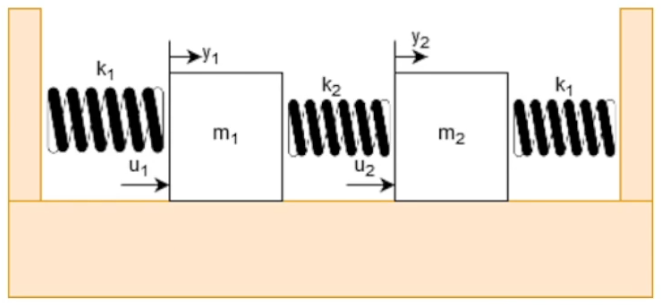

## Modellazione del sistema

Il sistema massa-molla in questione può essere visto come un sistema MIMO a due ingressi (le forze applicate ai due blocchi) e due uscite (lo spostamento dei due blocchi).

### Formulazione matematica

Dalla legge di Hooke, per la prima massa:


$$u_1 \left(t\right)-k_1 y_1 \left(t\right)-k_2 \left(y_1 \left(t\right)-y_2 \left(t\right)\right)=m_1 \ddot{y_1 } \left(t\right)$$



$$\ddot{y_1 } \left(t\right)=\frac{1}{m_1 }u_1 \left(t\right)-\frac{k_1 +k_2 }{m_1 }y_1 \left(t\right)+\frac{k_2 }{m_1 }y_2 \left(t\right)$$


Dalla legge di Hooke, per la seconda massa:


$$u_2 \left(t\right)-k_2 y_2 \left(t\right)-\left(k_1 +k_2 \right)y_2 \left(t\right)=m_2 \ddot{y_2 } \left(t\right)$$



$$\ddot{y_2 } \left(t\right)=\frac{1}{m_2 }u_2 \left(t\right)+\frac{k_2 }{m_2 }y_1 \left(t\right)-\frac{k_1 +k_2 }{m_2 }y_2 \left(t\right)$$


### Rappresentazione nello spazio di stato

Considerando le seguenti variabili di stato:

- $x_1 \left(t\right)=y_1 \left(t\right)$ la posizione del primo blocco

- $x_2 \left(t\right)=\dot{y_1 } \left(t\right)$ la velocità del primo blocco

- $x_3 \left(t\right)=y_2 \left(t\right)$ la posizione del secondo blocco

- $x_4 \left(t\right)=\dot{y_2 } \left(t\right)$ la velocità del secondo blocco

il sistema può essere espresso nella forma:


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \left(t\right)\\
\dot{x_2 } \left(t\right)\\
\dot{x_3 } \left(t\right)\\
\dot{x_4 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{k_1 +k_2 }{m_1 } & 0 & \frac{k_2 }{m_1 } & 0\\
0 & 0 & 0 & 1\\
\frac{k_2 }{m_2 } & 0 & -\frac{k_1 +k_2 }{m_2 } & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)\\
x_3 \left(t\right)\\
x_4 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{1}{m_1 } & 0\\
0 & 0\\
0 & \frac{1}{m_2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \left(t\right)\\
u_2 \left(t\right)
\end{array}\right\rbrack$$


$\left\lbrack \begin{array}{c}
y_1 \left(t\right)\\
y_2 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)\\
x_3 \left(t\right)\\
x_4 \left(t\right)
\end{array}\right\rbrack$+$\left\lbrack \begin{array}{cc}
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \left(t\right)\\
u_2 \left(t\right)
\end{array}\right\rbrack$

## Implementazione del sistema

% Operazioni preliminari
close all;
clear all; 
clc;

### Parametri del sistema

% Coefficienti elastici [N/m]
k1 = 1;
k2 = 2;

% Masse dei blocchi [kg]
m1 = 1;
m2 = 1.5;

### Matrici del sistema

% Matrici del sistema
A = [0,           1, 0,           0;
     -(k1+k2)/m1, 0, k2/m1,       0;
     0,           0, 0,           1;
     k2/m2,       0, -(k1+k2)/m2, 0];

B = [0,    0;
     1/m1, 0;
     0,    0;
     0,    1/m2];

C = [1, 0, 0, 0;
     0, 0, 1, 0];

D = [0, 0;
     0, 0];

### Definizione del sistema

% Sistema nello spazio di stato
plant = ss(A,B,C,D);

## Controllo del sistema

Una volta implementato il sistema da controllare, è necessario definire il controllore MPC ed i corrispettivi parametri.

### Parametri del controllo

% Periodo di campionamento
Ts = 0.1;   % 10 Hz

% Orizzonte di predizione
Hp = 10;

% Orizzonte di controllo
Hc = 2;

### Definizione del controllore

% Controllore MPC
mpcobj = mpc(plant,Ts,Hp,Hc);

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.


Si vuole controllare il sistema in modo che il primo blocco si muova di un metro e che il secondo blocco resti fermo nella sua posizione iniziale.

% Riferimento
yref = [1, 0];

Eseguendo una breve simulazione, ad esempio di 10 secondi, è possibile apprezzare l'efficacia del controllore su entrambi i blocchi.

% Simulazione del controllo
sim(mpcobj, 100, yref);

-->Converting model to discrete time.
-->Assuming output disturbance added to measured output #1 is integrated white noise.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


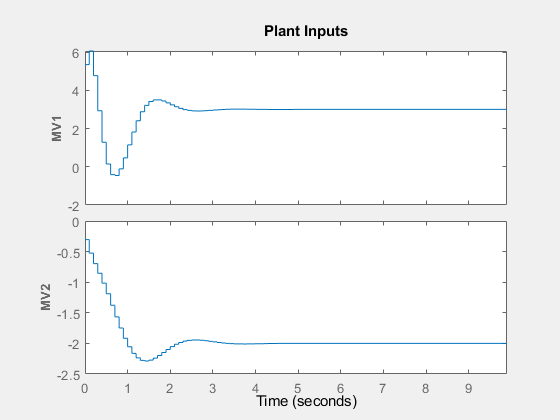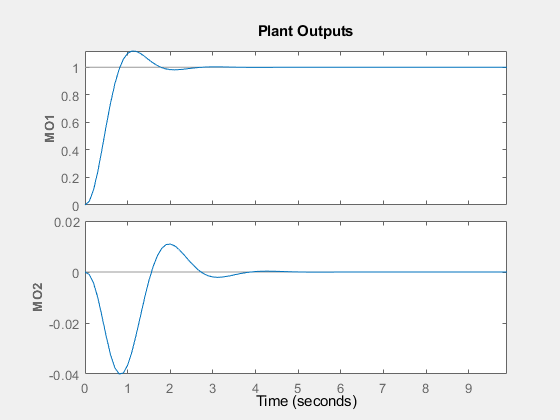

### Definizione di un vincolo sugli ingressi

Si supponga inoltre di voler imporre un vincolo sugli ingressi, in modo che ciascuno di essi sia limitato in un intervallo che va da -10 a 10 N:


$$-10<u<10$$


Per la definizione del vincolo è necessario agire sull'oggetto controllore, in particolare sui campi `Min` e `Max` della proprietà `ManipulatedVariables`.

% Vincolo sul valore minimo degli ingressi
mpcobj.ManipulatedVariables(1).Min = -10;
mpcobj.ManipulatedVariables(2).Min = -10;

% Vincolo sul valore massimo degli ingressi
mpcobj.ManipulatedVariables(1).Max = 10;
mpcobj.ManipulatedVariables(2).Max = 10;

Eseguendo nuovamente la simulazione, il solo vincolo sugli ingressi non ha alcun effetto perché questi sono già limitati nell'intervallo specificato.

% Simulazione del controllo
sim(mpcobj, 100, yref);

-->Converting model to discrete time.
-->Assuming output disturbance added to measured output #1 is integrated white noise.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


### Definizione di un vincolo sulla variazione degli ingressi

Si supponga inoltre di voler imporre un vincolo sugli ingressi in modo che la loro variazione, cioè l'ampiezza di ciascun gradino (che viene anche definita rate), sia limitata in un intervallo che va da -0.1 N a 0.1 N:


$$-0\ldotp 1<\Delta u<0\ldotp 1$$


Per la definizione del vincolo è necessario agire sull'oggetto controllore, in particolare sui campi `RateMin` e `RateMax` della proprietà `ManipulatedVariables`.

% Vincolo sul valore minimo del rate
mpcobj.ManipulatedVariables(1).RateMin = -0.1;
mpcobj.ManipulatedVariables(2).RateMin = -0.1;

% Vincolo sul valore massimo del rate
mpcobj.ManipulatedVariables(1).RateMax = 0.1;
mpcobj.ManipulatedVariables(2).RateMax = 0.1;

Eseguendo nuovamente la simulazione, è possibile apprezzare il soddisfacimento del vincolo sui rate.

% Simulazione del controllo
sim(mpcobj, 100, yref);

-->Converting model to discrete time.
-->Assuming output disturbance added to measured output #1 is integrated white noise.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


In particolare, il comportamento osservato è completamente differente da quello dei casi precedenti. Il sistema si dimostra più lento, ossia raggiunge più lentamente il suo valore finale dopo circa 6 secondi (contrariamente ai precedenti 5 secondi). Inoltre, i segnali di ingresso sono molto più regolari e limitati.

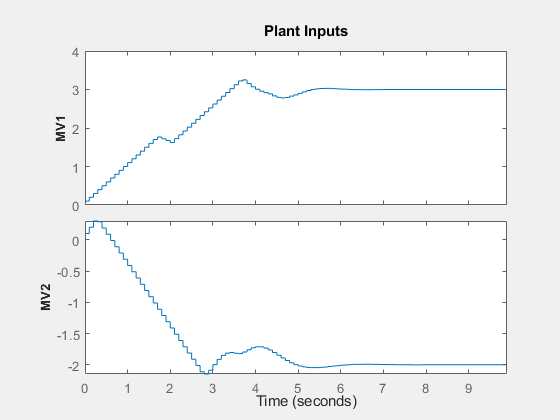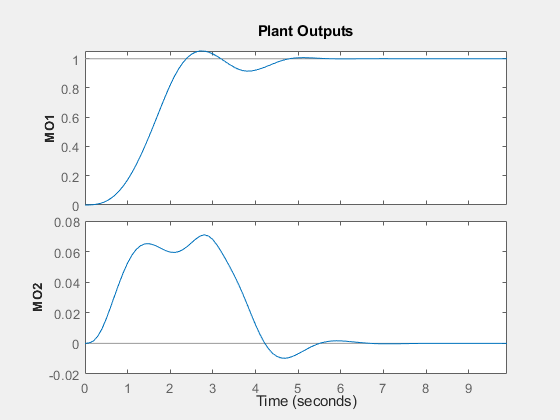

### Definizione di un vincolo sulle uscite

Si supponga inoltre di voler imporre un vincolo sulle uscite, in modo che ciascuna di esse sia limitata in un intervallo che va da 0 a 10 m:


$$0<y<10$$


Per la definizione del vincolo è necessario agire sull'oggetto controllore, in particolare sui campi `Min` e `Max` della proprietà `OutputVariables`.

% Vincolo sul valore minimo delle uscite
mpcobj.OutputVariables(1).Min = 0;
mpcobj.OutputVariables(2).Min = 0;

% Vincolo sul valore massimo delle uscite
mpcobj.OutputVariables(1).Max = 10;
mpcobj.OutputVariables(2).Max = 10;

Ancor prima di eseguire la simulazione ci si aspetta un comportamento analogo al caso precedente, in quanto l'uscita assume già un andamento limitato per gran parte della sua evoluzione, con una leggera correzione nel tratto in cui la seconda uscita si porta a valori minori di zero.

Eseguendo nuovamente la simulazione, è possibile apprezzare il soddisfacimento dei vincoli sui rate e sulle uscite.

-->Converting model to discrete time.
-->Assuming output disturbance added to measured output #1 is integrated white noise.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


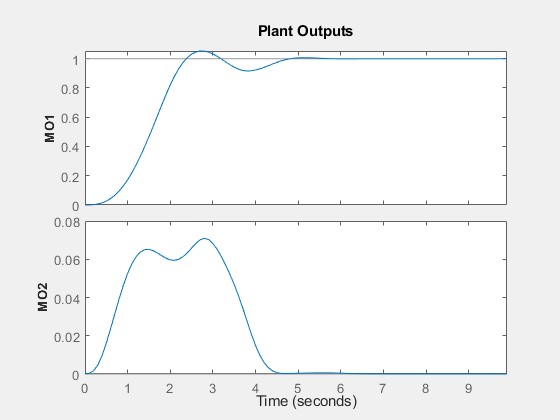

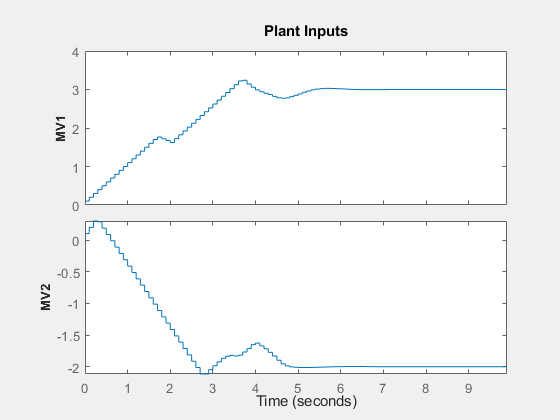

% Simulazione del controllo
sim(mpcobj, 100, yref);

Come predetto, a seguito della definizione del vincolo sulle uscite, la seconda uscita è limitata ad essere non negativa.

Può essere interessante confrontare l'evoluzione degli ingressi e delle uscite prima e dopo il vincolo sulle uscite.

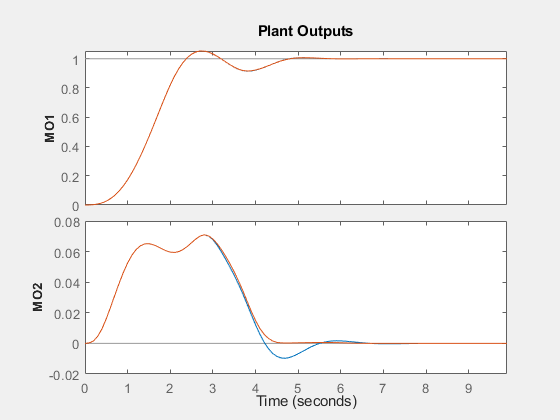

Come si evince dal confronto, l'unico andamento ad essere effettivamente soggetto ai vincoli imposti è quello relativo alla seconda uscita, che prima del vincolo presentava un piccolo picco per valori negativi prima di assestarsi al valore finale.

### Metodo alternativo per la simulazione

Oltre all'utilizzo del comando `sim(mpcobj,Ns,r)` e del toolbox MPC Designer, esiste un ulteriore metodo per eseguire una simulazione:

% Stato del sistema
xk = mpcstate(mpcobj);

% Vettore dei tempi per la simulazione
t = 0:Ts:10;

% Numero di step della simulazione
N = length(t);

N = 101

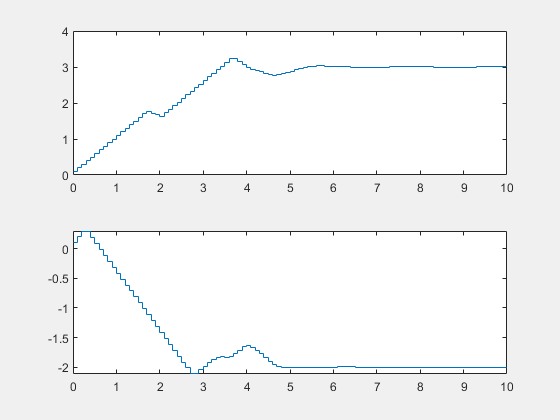


% Inizializzazione delle uscite
y = zeros(N,2);

% Inizializzazione degli ingressi
u = zeros(N,2);

% Ciclo di simulazione
for i=1:N
    y(i,:) = C*xk.Plant;
    u(i,:) = mpcmove(mpcobj, xk, y(i,:), yref);
end

% Evoluzione degli ingressi
figure(1)
subplot(2,1,1)
stairs(t, u(:,1))
subplot(2,1,2)
stairs(t, u(:,2))

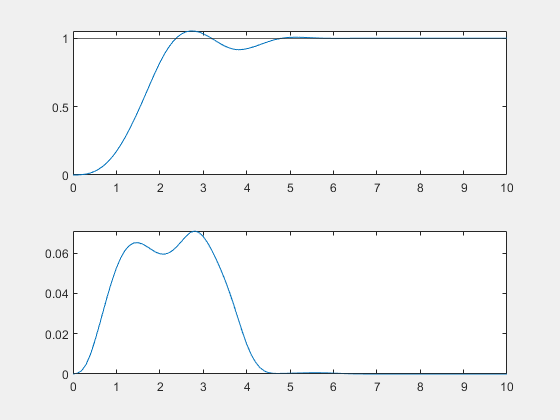


% Evoluzione delle uscite
figure(2)
subplot(2,1,1)
plot(t, y(:,1))
yline(yref(1));
subplot(2,1,2)
plot(t, y(:,2))
yline(yref(2));